# Analyzing Re-Alignment

## Recollect all data

load('results_BrainBonus2_P3.mat')
recollect_data

## calculation condition phases

theta_phases_condition = zeros([length(times), max(condition_positions), length(results)]);

freq_min = 4.5;
freq_max = 8;
for subj_ind = 1:length(results)
    theta_phases_subject = get_hilbert_phase(results{subj_ind}.trials, freq_min, freq_max, SamplingInterval);
    for cond_ind = 1:size(theta_phases_condition,2)
        theta_phases_condition(:,cond_ind,subj_ind) = circ_mean(theta_phases_subject(:,results{subj_ind}.condition_positions == cond_ind),[],2);
    end
end

erp_phases_condition = [];
for subj_ind = 1:length(results)
    for cond_ind = 1:size(theta_phases_condition,2)
        erp_phases_condition(:,cond_ind,subj_ind) = get_hilbert_phase(mean(results{subj_ind}.trials(:,:,results{subj_ind}.condition_positions == cond_ind),3), freq_min, freq_max, SamplingInterval);
    end
end


## Testing for different in phases

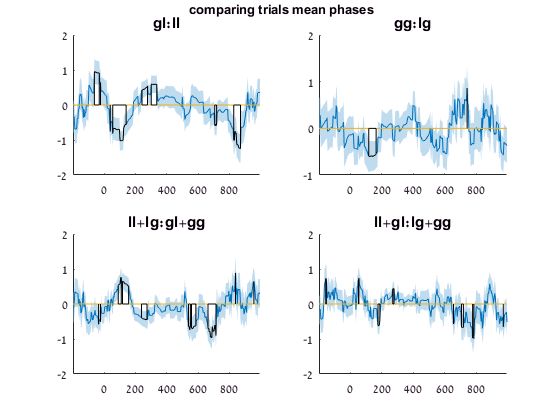

p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(theta_phases_condition, 3, 1, u, t, p_thresh, n, false);
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(theta_phases_condition, 4, 2, u, t, p_thresh, n, false);
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(theta_phases_condition, 1:2, 3:4, u, t, p_thresh, n, false);
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(theta_phases_condition, [1 3], [2 4], u, t, p_thresh, n, false);
title 'll+gl:lg+gg'
title_subplots 'comparing trials mean phases'

p_thresh = 0.01;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(theta_phases_condition, 3, 1, u, t, p_thresh, n, true)
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(theta_phases_condition, 4, 2, u, t, p_thresh, n, true)
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(theta_phases_condition, 1:2, 3:4, u, t, p_thresh, n, true)
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(theta_phases_condition, [1,3], [2,4], u, t, p_thresh, n, true)
title 'll+gl:lg+gg'
title_subplots 'comparing trials mean phases - bin'

## comparing to ERP

% p_thresh = 0.005;
% n = 1e3;
%{'ll','lg','gl','gg'}
figure;
subplot(2,2,1)
show_perm_results(total_erps, 3, 1, u, t)

Cluster 1: time points 125 to 154, t-sum = 82.3941, p-value = 0.010299.
Cluster 2: time points 157 to 158, t-sum = 3.59734, p-value = 0.725227.
Cluster 3: time points 13 to 14, t-sum = 3.56118, p-value = 0.729827.


title 'gl:ll'
subplot(2,2,2)
show_perm_results(total_erps, 4, 2, u, t)

Cluster 1: time points 146 to 210, t-sum = 338.197, p-value = 9.999e-05.
Cluster 2: time points 222 to 226, t-sum = 9.52241, p-value = 0.630337.
Cluster 3: time points 220 to 220, t-sum = 1.73041, p-value = 0.880912.


title 'gg:lg'
subplot(2,2,3)
show_perm_results(total_erps, 3:4, 1:2, u, t)

Cluster 1: time points 132 to 207, t-sum = 277.69, p-value = 9.999e-05.


title(join([join(condition_names(3:4)) ':' join(condition_names(1:2))]))
legend({'Alternative = Loss', 'Alternative = Gain'})
subplot(2,2,4)
show_perm_results(total_erps, [1,3], [2,4], u, t)

Cluster 1: time points 65 to 92, t-sum = 69.786, p-value = 0.0227977.
Cluster 2: time points 245 to 264, t-sum = 50.2967, p-value = 0.0624938.
Cluster 3: time points 27 to 32, t-sum = 12.3246, p-value = 0.537646.
Cluster 4: time points 12 to 14, t-sum = 5.55361, p-value = 0.747925.


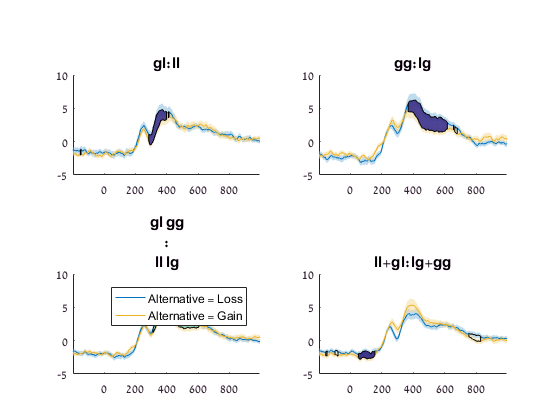

title 'll+gl:lg+gg'

ERP phases

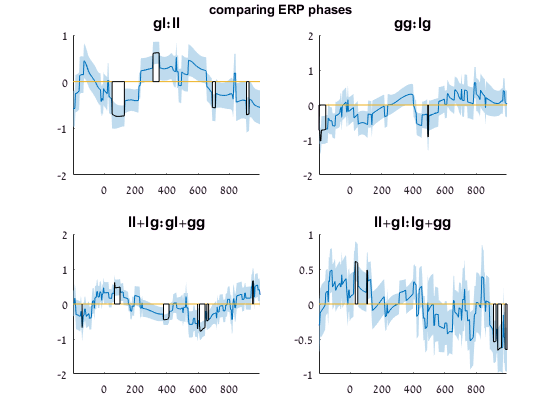

p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(erp_phases_condition, 3, 1, u, t, p_thresh, n, false)
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(erp_phases_condition, 4, 2, u, t, p_thresh, n, false)
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(erp_phases_condition, 1:2, 3:4, u, t, p_thresh, n, false)
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(erp_phases_condition, [1,3], [2,4], u, t, p_thresh, n, false)
title 'll+gl:lg+gg'
title_subplots 'comparing ERP phases'

p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(erp_phases_condition(:,:,1:17), 3, 1, u, t, p_thresh, n, true)
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(erp_phases_condition(:,:,1:17), 4, 2, u, t, p_thresh, n, true)
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(erp_phases_condition(:,:,1:17), 1:2, 3:4, u, t, p_thresh, n, true)
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(erp_phases_condition(:,:,1:17), [1,3], [2,4], u, t, p_thresh, n, true)
title 'll+gl:lg+gg'
title_subplots 'comparing ERP phases - bin'


## Testing phases using wavelets

phases_condition = zeros([length(freqs), length(times), max(condition_positions), length(results)]);
s_ = @squeeze;
for subj_ind = 1:length(results)
    phases_subject = s_(results{subj_ind}.phases);   
    for cond_ind = 1:size(phases_condition,3)
        phases_condition(:,:,cond_ind,subj_ind) = circ_mean(phases_subject(:,:,results{subj_ind}.condition_positions == cond_ind),[],3);
    end
end
% 
% erp_phases_condition = [];
% for subj_ind = 1:length(results)
%     for cond_ind = 1:size(theta_phases_condition,2)
%         erp_phases_condition(:,cond_ind,subj_ind) = get_hilbert_phase(mean(results{subj_ind}.trials(:,:,results{subj_ind}.condition_positions == cond_ind),3), freq_min, freq_max, SamplingInterval);
%     end
% end


p_thresh = 0.05;
n = 1e4;
figure;
subplot(2,2,1)
show_perm_phases(phases_condition, 3, 1, u, t, p_thresh, n, true, freqs);
title 'gl:ll'
subplot(2,2,2)
show_perm_phases(phases_condition, 4, 2, u, t, p_thresh, n, true, freqs);
title 'gg:lg'
subplot(2,2,3)
show_perm_phases(phases_condition, 1:2, 3:4, u, t, p_thresh, n, true, freqs);
title 'll+lg:gl+gg'
subplot(2,2,4)
show_perm_phases(phases_condition, [1 3], [2 4], u, t, p_thresh, n, true, freqs);
title 'll+gl:lg+gg'
title_subplots 'comparing trials mean phases - bin'


function show_perm_phases(data, left_inds, right_inds, u, t, p_thresh, num_permutations, is_bin, freqs)

set_default('is_bin', false);
set_default('p_thresh', 0.05);
set_default('num_permutations', 1e4);

is2dData = ndims(data) == 4;

if left_inds<0
    left_inds = find(1:4 ~= -left_inds);
end
if right_inds<0
    right_inds = find(1:4 ~= -right_inds);
end

if is2dData
    trial_g_1 = squeeze(circ_mean(data(:,u,left_inds, :),[], 3));
    if right_inds ~= 0
        trial_g_2 = squeeze(circ_mean(data(:,u,right_inds, :),[], 3));
    end    
else
    trial_g_1 = squeeze(circ_mean(data(u,left_inds, :),[], 2));
    if right_inds ~= 0
        trial_g_2 = squeeze(circ_mean(data(u,right_inds, :),[], 2));
    end
end


if right_inds == 0
    trial_g_2 = [];
    trial_g = trial_g_1;
else
    trial_g = circ_dist(trial_g_1,trial_g_2);
end

if is_bin
    trial_g = 1*(trial_g>0);
    thresh_g = 0.5;
else 
    thresh_g = 0;
end

if is2dData
    permutest_2dplot(trial_g, thresh_g, true, p_thresh, num_permutations, true, inf, true, t, freqs);
else
    permutest_plot(trial_g, thresh_g, true, p_thresh, num_permutations, true, inf, t, false);
end

end


function test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, t0, freq_min, freq_max, align_by_erp)


set_default('align_by_erp', false)

t_zero = t0;
N_subjects = length(results);
t=times(u);
total_powers_aligned = zeros([length(freqs), length(times), N_subjects]);

sub_powers_aligned = total_powers_aligned;
total_erps_aligned = zeros([ length(times)  N_subjects]);


for sub_ind = 1:N_subjects
    result = results{sub_ind};
    trials = result.trials;
    power_raw = result.power_raw;
    
    if align_by_erp
        phase_shifts = get_hilbert_phase_shift(mean(trials,3), freq_min, freq_max, SamplingInterval);
        phase_shifts = repmat(phase_shifts,1,size(trials,3));
    else
        phase_shifts = get_hilbert_phase_shift(trials, freq_min, freq_max, SamplingInterval);
    end
    shift = phase_shifts(find(times>t_zero,1),:);
    aligned_trials = align_trials_by_shift(trials, shift);
    aligned_erp = mean(aligned_trials(:,1,:),3);
    aligned_power = align_power_by_shift(power_raw, shift);
    aligned_power = norm_power_bl_range(squeeze(aligned_power), bl_range);
    
    sub_trials_aligned = bsxfun(@minus, aligned_trials, aligned_erp);
    sub_aligned_power = getPowerSpectra(sub_trials_aligned', SamplingInterval./1000, freqs);
    sub_aligned_power = norm_power_bl_range(sub_aligned_power, bl_range);
    
    total_powers_aligned(:,:,sub_ind) = squeeze(aligned_power);
    sub_powers_aligned  (:,:,sub_ind) = squeeze(sub_aligned_power);
    total_erps_aligned(:,sub_ind) = aligned_erp;
    
end

title_freq = sprintf('@ t=%d ms, f=%.1f-%.1f Hz', t_zero, freq_min, freq_max);
if align_by_erp
    title_freq = ['shift by subjects'' ERP' title_freq];
end

figure;
show_powers_tight(t, freqs, cat(3, ...
    squeeze(mean(total_powers(:,u,:),3)), ...
    squeeze(mean(sub_powers(:,u,:),3)), ...
    squeeze(mean(total_powers(:,u,:),3))-squeeze(mean(sub_powers(:,u,:),3)), ...
    mean(total_powers_aligned(:,u,:),3), ...
    mean(sub_powers_aligned(:,u,:),3), ...
    mean(total_powers_aligned(:,u,:),3)-mean(sub_powers_aligned(:,u,:),3)),...
    3, title_freq, 'Power [db]', [], ...
    {'total power', 'induced power', 'evoked power', 'aligned power', 'induced aligned power', 'evoked aligned power'})

figure;
subplot(1,2,1);
varplot(times, squeeze(mean(total_erps,2)))

title({'original trials'})
subplot(1,2,2);
varplot(times, total_erps_aligned)
title({'aligned trials ' title_freq})

end

function norm_power = norm_power_bl_range(power, bl_range)
bl_values = mean(mean(power(:, bl_range, :),3),2);
norm_power = 10 * log10(bsxfun(@rdivide,mean(power,3),bl_values));
end

